# Sprawozdanie z Laboratorium 1

Karolina Piotrowska

Zadanie 1

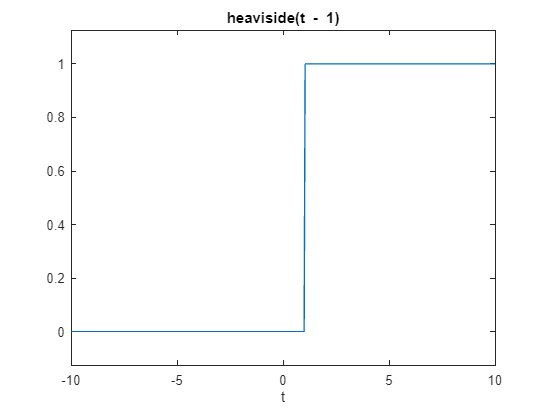

syms t s
syms a positive
a = 1;
f = heaviside(t-a);
Fs = laplace(f,t,s);
ezplot(f, [-10,10])

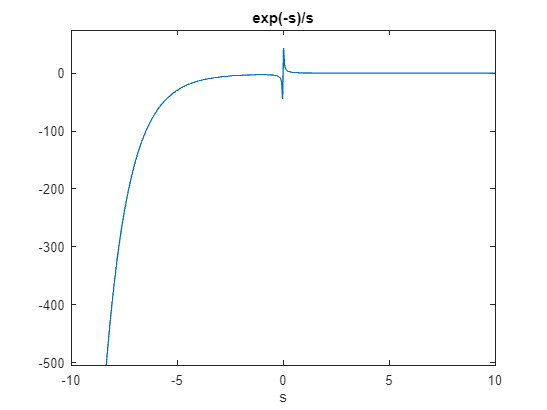

ezplot(Fs, [-10,10])

Zadanie 2

- czy bieguny są rzeczywiste? Nie, są nierzeczywiste 

- czy układ jest stabilny? Nie

licz = [0 0 1];
mian = [1000 500 400];
obiekt = tf(licz,mian);
[z,p,k] = tf2zp(licz, mian)


z =

  0×1 empty double column vector



p =   -0.2500 + 0.5809i
  -0.2500 - 0.5809i


k = 1.0000e-03

%z - zera układu
%p - bieguny układu
%k - wzmocnienie
oscylacyjny = (500/(2*sqrt(1000*400))) < 1

oscylacyjny = logical
   1


G = 1/((s - p(1))*(s - p(2))) %postać sfaktoryzowana

$$G = \frac{1}{\left(s+\frac{1}{4}-\frac{3\,\sqrt{3}\,\sqrt{5}\,\mathrm{i}}{20}\right)\,\left(s+\frac{1}{4}+\frac{3\,\sqrt{3}\,\sqrt{5}\,\mathrm{i}}{20}\right)}$$

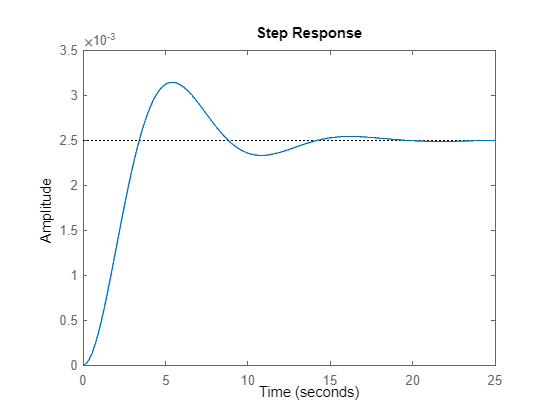

%oscylacyjny
step(licz,mian)

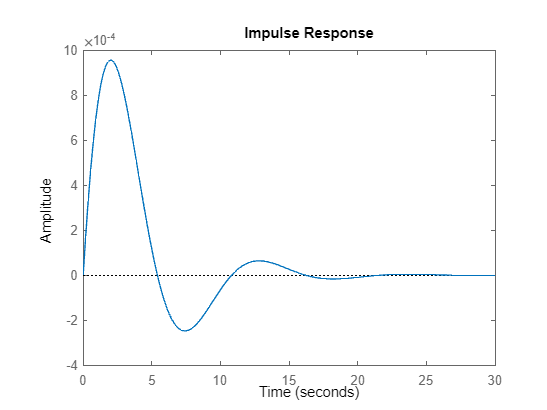

impulse(licz,mian) 

mian = [10 10000 40];
oscylacyjny = (10000/(2*sqrt(10*40))) < 1

oscylacyjny = logical
   0


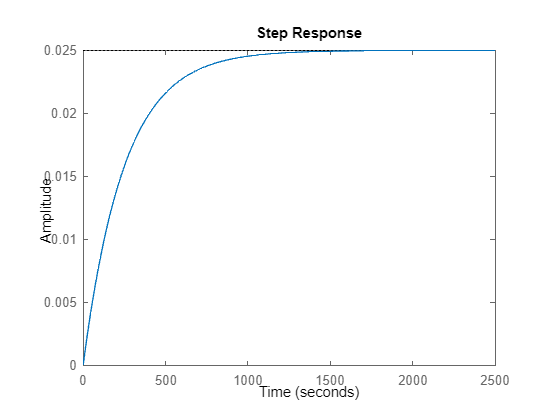

%tłumiony
step(licz,mian)

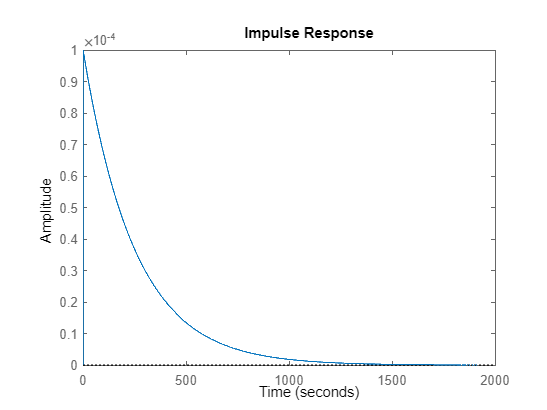

impulse(licz,mian) 

Zadanie 3

obiekt = zpk(-1/4, [0 -5 -0.1], 2)

obiekt =
 
    2 (s+0.25)
  ---------------
  s (s+5) (s+0.1)
 
Continuous-time zero/pole/gain model.



Zadanie 4

mian = [1000 500 400];
[A,B,C,D] = zp2ss(z,p,k)

A =    -0.5000   -0.6325
    0.6325         0


B =      1
     0


C =          0    0.0016


D = 0

[A1,B1,C1,D1] = tf2ss(licz,mian)

A1 =    -0.5000   -0.4000
    1.0000         0


B1 =      1
     0


C1 = 1.0e-03 *

         0    1.0000


D1 = 0

equal = A==A1 & B==B1 & C==C1 & D==D1

equal = 2×2 logical array
   1   0
   0   0


%macierze nie są takie same
step(A,B,C,D)

impulse(A,B,C,D)

step(A1,B1,C1,D1)

impulse(A1,B1,C1,D1)

%odpowiedzi są takie same

Zadanie 5

licz1 = [0 1 1];
mian1 = [1 5 1];
licz2 = [0 0 1];
mian2 = [1 1 -2 1];
sys1 = tf(licz1,mian1);
sys2 = tf(licz2,mian2);
srs = sys1 * sys2 %połączenie szeregowe

srs =
 
                  s + 1
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 3 s + 1
 
Continuous-time transfer function.



par = sys1 + sys2 %połączenie równoległe

par =
 
          s^4 + 2 s^3 + 4 s + 2
  -------------------------------------
  s^5 + 6 s^4 + 4 s^3 - 8 s^2 + 3 s + 1
 
Continuous-time transfer function.



fdb = feedback(sys1,sys1) %ujemne sprzężenie zwrotne

fdb =
 
       s^3 + 6 s^2 + 6 s + 1
  --------------------------------
  s^4 + 10 s^3 + 28 s^2 + 12 s + 2
 
Continuous-time transfer function.

